% C_i Polynomial Calculation
A = [1, 1;
    -1, 3;]

B = [-2;
    0]

C = A \ B

% Trash Can
-8/9*(1+1/sqrt(10))
-8/9*(1-1/sqrt(10))

s = tf('s');
% System Define
sys = (4*s-8)/(s^2 + 2*s - 9)
% sys = 10/(s^2 + 2*s + 10)

% DC Gain
GAIN = dcgain(sys)

% Poles
p = pole(sys)

% Satability
isStable = all(real(p)<0)

% Change Param
% HW2 1a
% Check input response
p1 = -1 + sqrt(10);
p2 = -1 - sqrt(10);
c1 = -(8/9)*(1 + 1/sqrt(10));
c2 = -(8/9)*(1 - 1/sqrt(10));
cons = 16/9;

y_ana = @(t) c1*exp(p1*t) + c2*exp(p2*t) + cons;

a1 = 2;
a0 = -9;
b0 = -16;

f  = @(t,x) [ x(2);
              -a1*x(2) - a0*x(1) + b0 ];

x0 = [0; 0];
[t,X] = ode45(f, [0 10], x0);

y_ode = X(:,1);
ya    = y_ana(t);

figure;
plot(t, ya,  'r--','LineWidth',1.5); hold on;
plot(t, y_ode,'b'  ,'LineWidth',1.5); hold off;
grid on; xlabel('t'); ylabel('y(t)');
legend('analytic','ode45','Location','best');
title('y(t) comparison');

% Change Param
% HW2 1b
% Check input response
p1 = -1;
p2 = -1;
c1 = -2;
c2 = -2/3;
cons = 2;

y_ana = @(t) exp(-t).*(c1*cos(3*t) + c2*sin(3*t)) + cons;

a1 = 2;
a0 = 10;
b0 = 20; 

f  = @(t,x) [ x(2); -a1*x(2) - a0*x(1) + b0 ];

x0 = [0; 0];

[t,X] = ode45(f, [0 10], x0)

y_ode = X(:,1);
ya    = y_ana(t);

figure;
plot(t, ya,  'r--','LineWidth',1.5); hold on;
plot(t, y_ode,'b'  ,'LineWidth',1.5); hold off;
grid on; xlabel('t'); ylabel('y(t)');
legend('analytic','ode45','Location','best');
title('y(t) comparison');

% HW2 2c
sys = tf(4,[1 3]);

t = out.yout.Time;
y = out.yout.Data;
u = out.step.Data;

yss  = dcgain(sys);  
tol = 0.05 * yss;
idx = find(abs(y - yss) <= tol, 1);  
t_s = t(idx);

figure;
plot(t, y, 'b', 'LineWidth', 1.5); hold on; grid on;
plot(t, u, '--c', 'LineWidth', 1);

yline(yss, '--r', sprintf('y_{ss} = %.2f', yss));
xline(t_s, ':g', sprintf('t_s = %.2f s', t_s));

xlabel('Time (s)');
ylabel('Amplitude');
title('Simulink Step Response with Steady-State Value and Settling Time');
legend('y(t)','u(t)','y_{ss}','t_s','Location','Southeast');

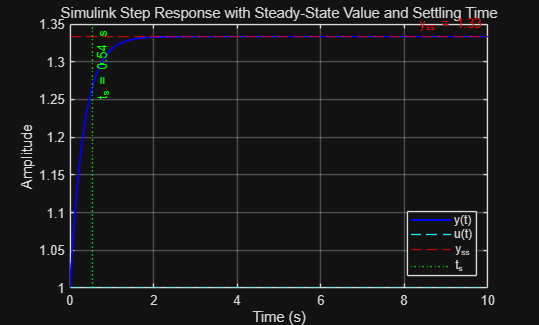

% HW2 2d
sys = tf(4,[1 3]);

t = out.yout.Time;
y = out.yout.Data;
u = out.step.Data;

yss  = dcgain(sys);  
tol = 0.05 * yss;
idx = find(abs(y - yss) <= tol, 1);  
t_s = t(idx);

figure;
plot(t, y, 'b', 'LineWidth', 1.5); hold on; grid on;
plot(t, u, '--c', 'LineWidth', 1);

yline(yss, '--r', sprintf('y_{ss} = %.2f', yss));
xline(t_s, ':g', sprintf('t_s = %.2f s', t_s));

xlabel('Time (s)');
ylabel('Amplitude');
title('Simulink Step Response with Steady-State Value and Settling Time');
legend('y(t)','u(t)','y_{ss}','t_s','Location','Southeast');